# Math Programming Final Project

## Maxwell Greene

## Wednesday, May 16th, 2018

## Import Variables & Plot Data

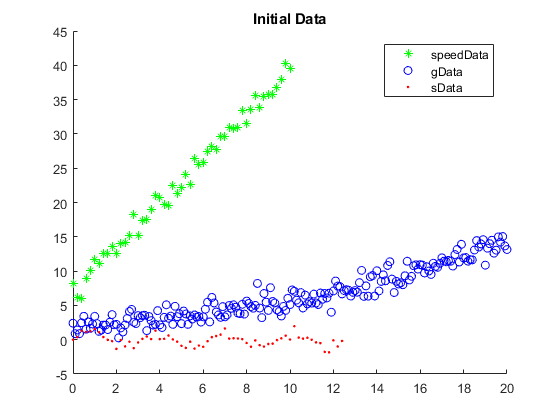

global sData gData speedData;             %Create global variables (function access)
sData = csvread('sData.csv');             %Import sData
gData = csvread('gData.csv');             %Import gData
speedData = csvread('speedData.csv');     %Import speedData

figure('Name','Plot of data'); hold on;
plot(speedData(:,1),speedData(:,2),'*g'); %Plot speedData
plot(gData(:,1),gData(:,2),'ob');         %Plot gData
plot(sData(:,1),sData(:,2),'.r');         %Plot sData
title('Initial Data'); 
hold off;
legend('speedData','gData','sData');      %Draw legend on figure 

# GData

## I assume the form of a polynomial function for fitting this data. The functions 'ExpEval' and 'ExpError' accept a vector of variable length corrosponding to the coefficients of each exponent of x in a polynomial function.

I start with a guess of a 2nd order polynomial: $y = .05x^2-.05x+5$

evalNum = 2;                                %Sets degree of polynomial to 2
A = [5 .05 .05];                            %Define values of coefficients for estimate
[error,value] = ExpEval(gData(:,1),gData(:,2),A);%Return error at initial value A

The error from these values was

error           %Displays the scalar error calculated in ExpEval

error = 8.1433e+03

Plot the data to visualize the guess curve.

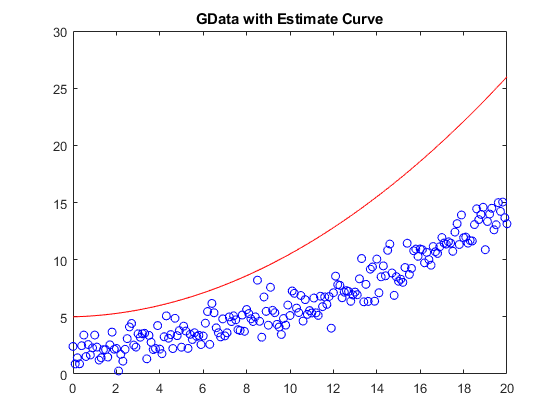

plot(gData(:,1),gData(:,2),'ob',gData(:,1),value,'-r'); %Plots data and estimate
title('GData with Estimate Curve');

## Now, I find the function with a minimum error.

x0 = zeros(evalNum+1);                  %Define starting values for fminsearch
optInputs = fminsearch(@ExpError,x0);   %Optimum inputs for min of error func
[optError,optValue]=ExpEval(gData(:,1),gData(:,2),optInputs);%Value & error @ optInputs

The error for the optimized inputs values is

optError         %Outputs calculated error corresponding to optimum inputs

optError = 210.9412

Notice this error is drastically smaller than our guess.

Our optimum inputs were:

optInputs(:,1)   %Outputs the calculated optimum inputs

ans =     2.1374
    0.0944
    0.0256


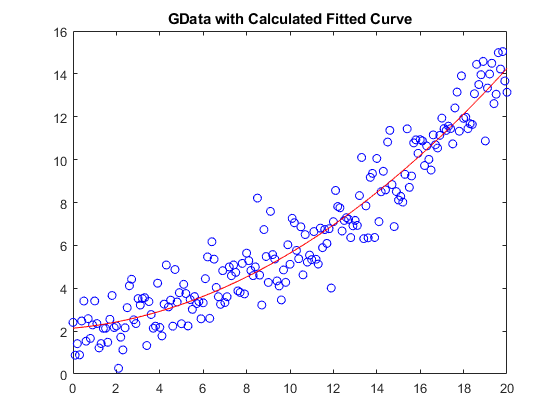

plot(gData(:,1),gData(:,2),'ob',gData(:,1),optValue,'-r'); %Plots GData & fitted curve
title('GData with Calculated Fitted Curve');

# SData

## I assume the form of a sin function for fitting this data. The functions 'SinEval' and 'SinError' accept a vector of length 3, which corrospond to the amplitude, period and phase shift, respectively.

I start with a guess of a sin function: $y = 2sin(1.5(x+\frac{\pi}{4})$.

guess = [2 1.5 pi/4];    %Gives values for estimate of the form [amplitude period phase]
[error,value] = SinEval(sData,guess); %Sets error to scalar error of value of function

The error for this guess was

error

error = 163.4848

Plot the data to visualize the guess curve.

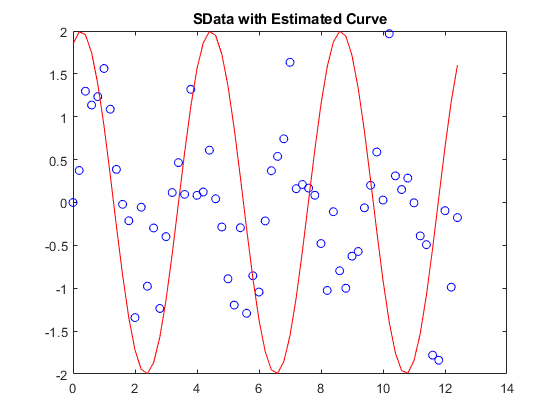

plot(sData(:,1),sData(:,2),'ob',sData(:,1),value,'-r'); %Plots sData and estimate
title('SData with Estimated Curve');

## Now, I find the function with a minimum error.

x0 = [1 2 0];       %Define values for coefficients to evaluate estimate
optInputs = fminsearch(@SinError,x0);   %Returns inputs at fminsearch of error function
[optError,optValue] = SinEval(sData,optInputs);%Evaluates error function at optInputs

The error for the optimized inputs values is

optError            %Displays optimum error

optError = 12.9819

Notice this error is drastically smaller than our guess.

Our optimum values were:

optInputs      %Displays optimum inputs [amplitude period phase-shift]

optInputs =     0.9490    2.0113   -0.0146


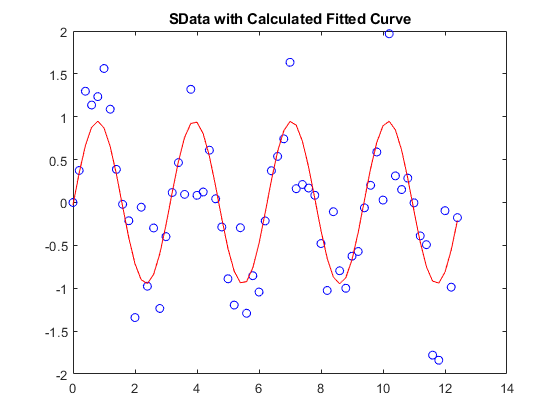

plot(sData(:,1),sData(:,2),'ob',sData(:,1),optValue,'-r');  %Plots data and fitted curve
title('SData with Calculated Fitted Curve');

# SpeedData

## I assume the form of a polynomial function for fitting this data. The functions 'LinEval' and 'LinError' accept a vector of variable length corrosponding to the coefficients of each exponent of x in a polynomial function.

I start with a guess of a 1st order polynomial: $y = 10x+5$

evalNum = 1;        %Sets degree of polynomial to 1
guess = [5 10];    %Gives values for coefficients to evaluate estimate
[error,value] = LinEval(speedData(:,1),speedData(:,2),guess);

The error from these values was

error

error = 7.2033e+04

Plot the data to visualize the guess curve.

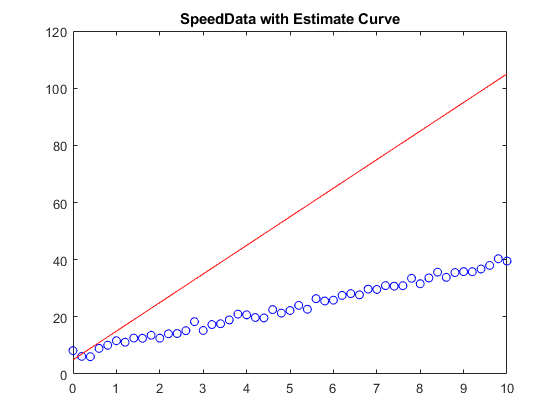

plot(speedData(:,1),speedData(:,2),'ob',speedData(:,1),value,'-r'); 
title('SpeedData with Estimate Curve');

## Now, I find the function with a minimum error.

x0 = zeros(evalNum+1);
optInputs = fminsearch(@LinError,x0);
[optError,optValue] = ExpEval(speedData(:,1),speedData(:,2),optInputs);

The error for the optimized inputs values is

optError

optError = 48.7744

Notice this error is drastically smaller than our guess.

Our optimum values were:

optInputs(:,1)

ans =     6.9871
    3.2323


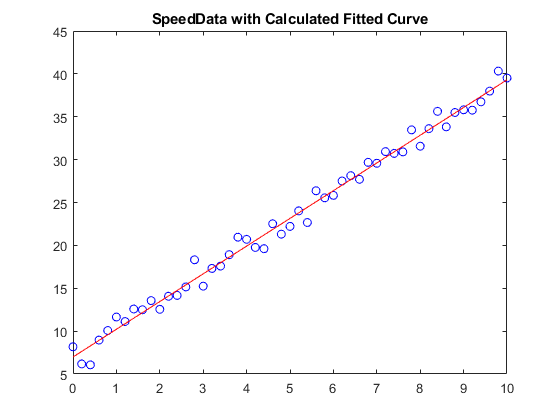

plot(speedData(:,1),speedData(:,2),'ob',speedData(:,1),optValue,'-r'); 
title('SpeedData with Calculated Fitted Curve');